# 1D Muscle Model based on the **Hill** 2-Element Model

clear all
addpath(genpath('../'));

## Model Overview

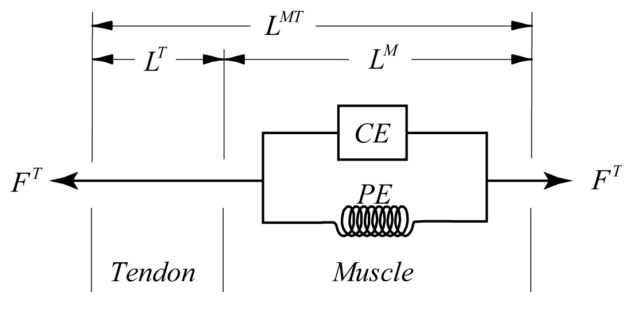

Schematic taken from citestartAnderson2007citeend.

Global plotting options

fnum = 1;
opt_grid = 'on';
opt_hold =  'off';
splotx = 0;
sploty = 0;

## Global muscle properties

$L_{rest}$ is the muscle resting length, $P_{max}$ is the maximum force the muscle can produce and $v_{max}$ is the maximum velocity of shortening.

L_REST = 0.5; %mm
F_MAX = 5; %N
V_MAX = -1.5; %mm/s

$a$ and $b$ are shape constants for the muscle force-velocity relationship

% muscle model constants
a = 0.25;
b = a*V_MAX/F_MAX;

## Parallel elastic element

This element represents the passive response of the muscle upon streching greater than resting length.

Note that $L_{PE}=L_{TOT}=L_{CE}$

The form of the passive relationship is not easily found in literature and is implemented in a straight forward way here to match the requirements of an exponential form which is non-zero above $L_{rest}$;


$$F_{PE} = F_{MAX}c \times [e^{L_{TOT}/L{REST}-1}-1]$$


Parameter $c$ is introduced to tune the shape of the curve. 

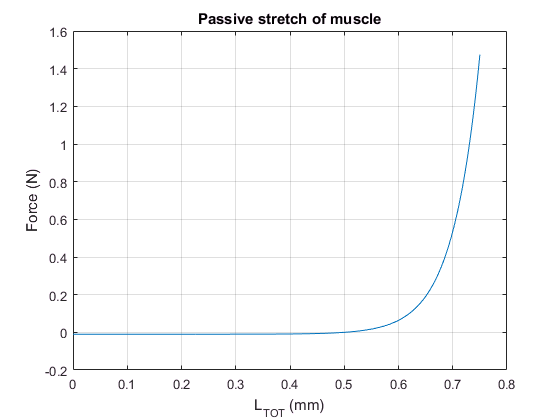

L_TOT = (0:0.001:L_REST*1.5);
F_PE = parallel_elastic(L_TOT, L_REST);

xvec = L_TOT;
yvec = F_PE;
ftitle = 'Passive stretch of muscle';
xtitle = 'L_{TOT} (mm)';
ytitle = 'Force (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

## Contractile element

This element is reponsible for the active force production in the muscle. The total force is given in the form;


$$F_{CE} = \alpha(t) \times F_{vel}(V)\times F_{len}(L_{TOT})$$


As a first step, we assume that the muscle is fully tetanized, i.e. $\alpha(t)  = 1$. 

Force-velocity

Taken from citestartChallis1994aciteend, based on citestartHill1938citeend.


$$F_{VEL} = \frac{a(V_{MAX}-V)}{(b-V)}$$


where $a$ and $b$ have been fit to $V_{MAX}$ and $F_{MAX}$.

Note that velocity is taken as negative when the muscle is shortening, i.e. concentric contractions. To account for eccentric contractions a temporary adjustment is made. When velocity is positive:


$$F_{VEL} = \frac{F_{MAX}^{ECC}-F_{MAX}}{|V_{MAX}|}\times V + F_{MAX}$$


Where $F_{MAX}^{ECC} > F_{MAX}$ is the force under eccentric contraction. And the steepness of the curve is defined such that $F_{MAX}^{ECC}$ is reached at $|V_{MAX}|$.

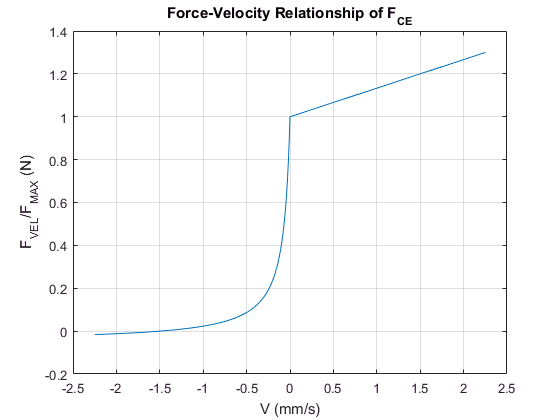

V = -1.5*V_MAX:-0.01:1.5*V_MAX;
F_MAXECC = 1.2*F_MAX;

F_VEL = force_vel(V_MAX, V, F_MAX, F_MAXECC);

xvec = V;
yvec = F_VEL;
ftitle = 'Force-Velocity Relationship of F_{CE}';
xtitle = 'V (mm/s)';
ytitle = 'F_{VEL}/F_{MAX} (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

Force-Length

Taken from citestartChallis1994aciteend, based on citestartHatze1981citeend;


$$F_{LEN}=F_{MAX}[e^{-(\frac{Q-1}{SK})^2}]$$


where $Q = L_{CE}/L_{REST}$ and$SK$ is a material parameter.

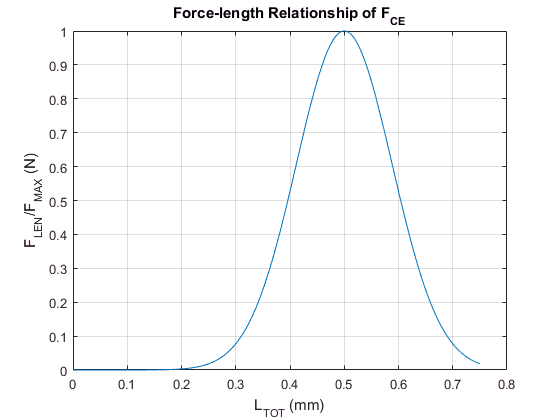

F_LEN = force_length(L_TOT, L_REST);

xvec = L_TOT;
yvec = F_LEN;
ftitle = 'Force-length Relationship of F_{CE}';
xtitle = 'L_{TOT} (mm)';
ytitle = 'F_{LEN}/F_{MAX} (N)';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)

Now, returning to the contractile elment total force (normalising the indiviual relatioships to maximum force); 


$$F_{CE} = F_{MAX} \times \frac{a(V_{MAX}-V)}{(b-V)F_{MAX}} \times e^{-(\frac{L_{CE}/L_{REST}-1}{SK})^2}$$


recall that the muscle is currently fully tetanised. 

## Total muscle force

Total force of the muscle is given by summing the passive and active parts; 


$$F_{MUSC} = F_{CE}+F_{PE}$$



$$F_{MUSC} =  F_{MAX} \times \{ \frac{a(V_{MAX}-V)}{(b-V)F_{MAX}} \times 
e^{-(\frac{L_{CE}/L_{REST}-1}{SK})^2} + c[e^{L_{TOT}/L{REST}-1}-1] \}$$


Constant velocity

Now, consider the muscle shortening at a constant velocity.

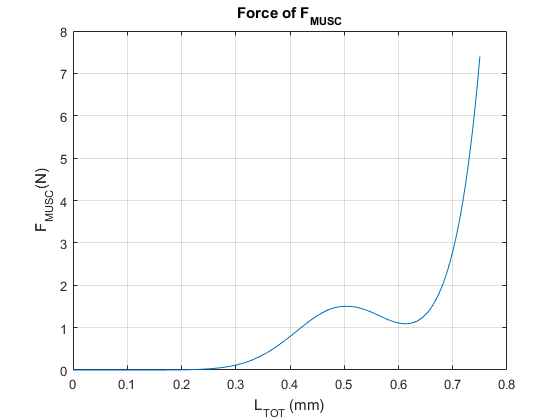

% activation
alpha = 1;
% loading velocity
V = 0.1*V_MAX;
F_MUSC = force_muscle(L_TOT, L_REST, V_MAX, V, F_MAX, alpha, F_MAXECC);

xvec = L_TOT;
yvec = F_MUSC;
ftitle = 'Force of F_{MUSC}';
xtitle = 'L_{TOT} (mm)';
ytitle = 'F_{MUSC}(N)';
opt_hold = 'off';
plotxy(xvec, yvec, fnum, ftitle, xtitle, ytitle, opt_grid, opt_hold, ...
    splotx, sploty)